%Note that we have a 3 link manipulator, with an actuator at the start of
%each link
%each actuator torque needs to both support the weight of itself plus the parts of the serial
%manipulator beyond it, and it additionally needs to support the torque
%required to meet desired angular acceleration specs.

%calculate the max torque-speed combo for the 3rd actuator so that it can
%be properly spec'd

%global parameters...
%for PVC pipe
mass_per_m = 12 / 100 * 0.453592 * 0.3048; %kg/m 15=lb/100ft

%for link/motor three
L_link3 = 0.1016; %four inches
m_link3 = L_link3 * mass_per_m; %kg
m_motor3 = 0.047; %kg

%worst case motor needs for actuator 3
[torque3, ang_vel3] = actuator_three_specs (L_link3, m_link3, m_motor3)

torque3 = 43.2761

ang_vel3 = 37.5000

plot([0 210], [220 0]) %motor specs curve, stall torque then rpm
hold on
plot(torque3, ang_vel3,'r*')
label = {'(43, 38)'}

label = 1×1 cell array
    {'(43, 38)'}


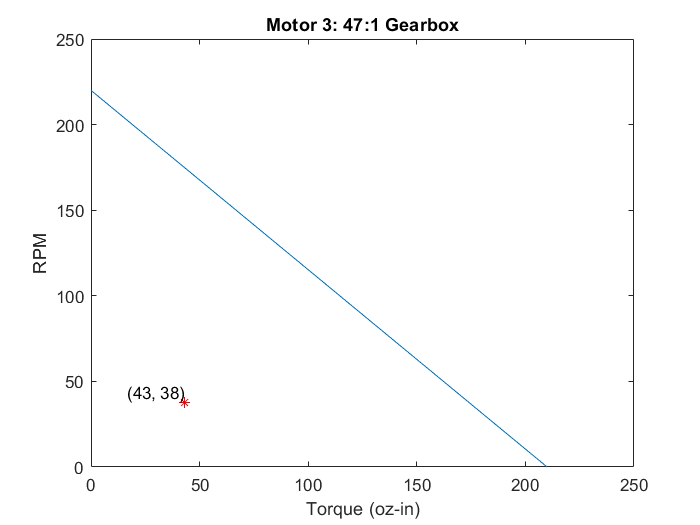

text(torque3, ang_vel3,label,'VerticalAlignment','bottom','HorizontalAlignment','right')
xlabel("Torque (oz-in)")
ylabel("RPM")
title("Motor 3: 47:1 Gearbox")
hold off

%for link/motor two
L_link2 = 0.203; %eight inches
m_link2 = L_link2 * mass_per_m; %kg
m_motor2 = 0.104; %kg

%worst case motor needs for actuator 2
[torque2, ang_vel2] = actuator_two_specs (L_link2, m_link2, m_motor2, L_link3, m_link3, m_motor3)

torque2 = 145.9180

ang_vel2 = 37.5000

plot([0 210], [220 0]) %motor specs curve, stall torque then rpm
hold on
plot(torque2, ang_vel2,'r*')
label = {'(146, 38)'}

label = 1×1 cell array
    {'(146, 38)'}


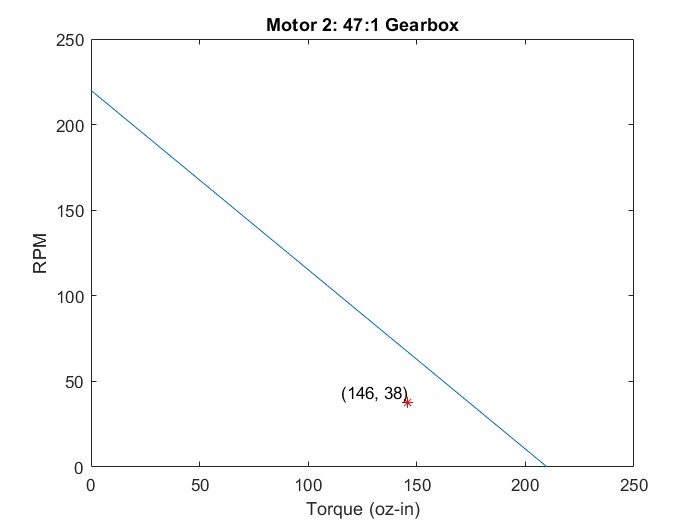

text(torque2, ang_vel2,label,'VerticalAlignment','bottom','HorizontalAlignment','right')
xlabel("Torque (oz-in)")
ylabel("RPM")
title("Motor 2: 47:1 Gearbox")
hold off

%for link/motor three
L_link2 = 0.3048; %twelve inches
m_link2 = L_link2 * mass_per_m; %kg
m_motor2 = 0.104; %kg

%note motor 1 is very different loading configuration! Skip writing reusale
%script and just pull from hand calcs for worst case torque/rpm
%here resistive load can be seen as primarily moment of intertia from 
%outstretched links but even more so, friction in rotational contact face!

%worst case motor needs for actuator 1
torque1 = 218;
ang_vel1 = ang_vel2;
plot([0 630], [76 0]) %motor specs curve, stall torque then rpm
hold on
plot(torque1, ang_vel1,'r*')
label = {'(218, 38)'}

label = 1×1 cell array
    {'(218, 38)'}


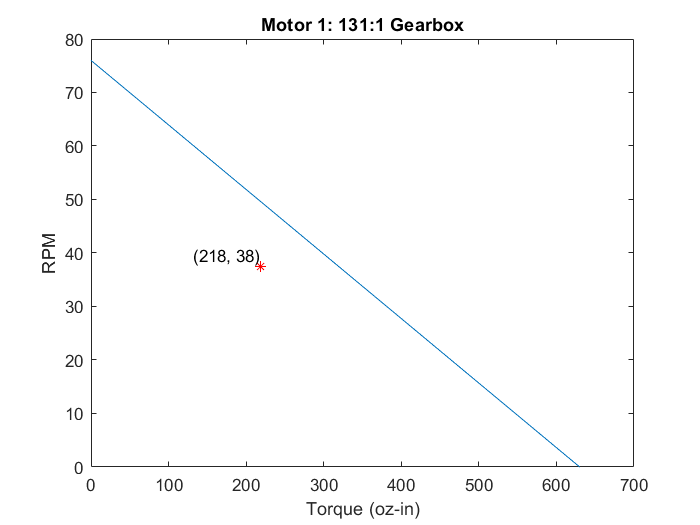

text(torque1, ang_vel1,label,'VerticalAlignment','bottom','HorizontalAlignment','right')
xlabel("Torque (oz-in)")
ylabel("RPM")
title("Motor 1: 131:1 Gearbox")
hold off